使用**内置粒子群算法 **[`particleswarm`](https://ww2.mathworks.cn/help/releases/R2022a/gads/particleswarm.html?searchHighlight=pso&s_tid=doc_srchtitle&#d123e60264) 对PID的参数进行调节。

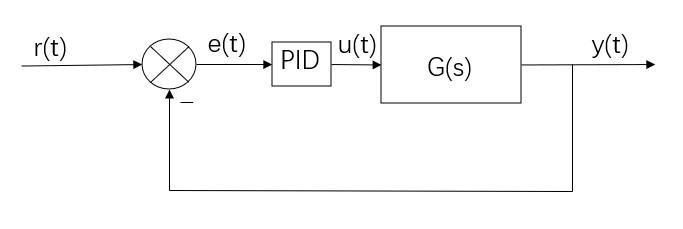

闭环控制

误差e=y-r，计算均方误差mse作为粒子的适应度。

clc
clear
close all

% 定义被控系统
global Wn zeta
Wn = 1;         % 固有频率 1rad/s
zeta = 0.5;     % 欠阻尼
Num = [Wn^2];
Den = [1, 2*zeta*Wn, Wn^2]; 

sys = tf(Num, Den)

sys =
 
       1
  -----------
  s^2 + s + 1
 
Continuous-time transfer function.



pole(sys)       % 系统有两个具有负实部的极点，系统稳定

ans =   -0.5000 + 0.8660i
  -0.5000 - 0.8660i



% 生成参考信号
global tau T X0 h t r
tau = 10;
Tmax = 50;
X0 = [0;0];
h = 0.01;
T = 0:h:Tmax;
[r,t] = gensig('square',tau, Tmax, h);  % 参考信号

% 内置粒子群算法
N = 3;  % 例子维度
lb = [0; 0; 0];
ub = [5; 5; 5];
options = optimoptions('particleswarm','SwarmSize',20,'MaxIterations',20,'HybridFcn',@fmincon, 'Display', 'iter');

[x,fval,exitflag,output] = particleswarm(@calculate, N, lb, ub, options);


                                 Best            Mean     Stall
Iteration     f-count            f(x)            f(x)    Iterations
    0              20         0.05847          0.1366        0
    1              40         0.03726           8.288        0
    2              60         0.03726         0.08263        1
    3              80         0.03726         0.06464        2
    4             100         0.03725         0.04711        0
    5             120         0.03725         0.04164        0
    6             140         0.03725         0.04016        0
    7             160         0.03724         0.04195        0
    8             180         0.03722         0.03958        0
    9             200         0.03722         0.04067        1
   10             220         0.03721         0.03885        0
   11             240         0.03721           0.038        1
   12             260          0.0372         0.03727        0
   13             280          0.0372         0.

fprintf('最终最优参数：');
disp(x)

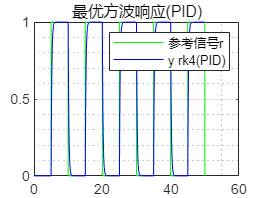

% PID控制
Kp = x(1);
Ki = x(2);
Kd = x(3);
global sum_e e_last
sum_e = 0;     
e_last = 0;

%%%%%%%% 使用龙格库塔法求解系统响应 %%%%%%%%
N=length(T);
X=zeros(length(X0),N);
X(:,1)=X0;
input = zeros(length(X0),1);
for i =2:N        
    X_k = X(:,i-1);
    t_k = T(i-1);
    
    if mod(t_k, tau) <=5
        ref = 0;
    else
        ref = 1;
    end
    
    u = PID(ref, X_k(1), h, Kp, Ki, Kd);
    input(i) = u;

    K1=fnc(t_k,X_k, u);
    K2=fnc(t_k+h/2,X_k+h/2*K1, u);
    K3=fnc(t_k+h/2,X_k+h/2*K2, u);
    K4=fnc(t_k+h,X_k+h*K3, u);
    
    X(:,i)=X_k + h/6*(K1+2*K2+2*K3+K4);
end

figure()
plot(t, r, 'g', T, X(1,:), 'b') % X(1,:)为系统的输出
title("最优方波响应(PID)")
legend("参考信号r","y rk4(PID)")
grid on
grid minor

function mse = calculate(x)
    % 初始化PID
    Kp = x(1);
    Ki = x(2);
    Kd = x(3);
    global sum_e e_last tau T X0 h r
    sum_e = 0;     
    e_last = 0;
    
    %%%%%%%% 使用龙格库塔法求解系统响应 %%%%%%%%
    N=length(T);
    X=zeros(length(X0),N);
    X(:,1)=X0;
    input = zeros(length(X0),1);
    for i =2:N        
        X_k = X(:,i-1);
        t_k = T(i-1);
        
        if mod(t_k, tau) <=5
            ref = 0;
        else
            ref = 1;
        end
        
        u = PID(ref, X_k(1), h, Kp, Ki, Kd);
        input(i) = u;

        K1=fnc(t_k,X_k, u);
        K2=fnc(t_k+h/2,X_k+h/2*K1, u);
        K3=fnc(t_k+h/2,X_k+h/2*K2, u);
        K4=fnc(t_k+h,X_k+h*K3, u);
        
        X(:,i)=X_k + h/6*(K1+2*K2+2*K3+K4);
    end
    
    output = X(1,:)';
    e = r - output;
    % 均方误差
%     mse = sum(e.^2)/length(e);
    % 平均误差
    e = abs(e);
    mse = sum(e)/length(e);
end
    
function dx = fnc(t, x, u)
    global Wn zeta
    dx = zeros(length(x), 1);
    dx(1) = x(2);
    dx(2) = -Wn^2*x(1) - 2*zeta*Wn*x(2) + Wn^2*u;
end
